+

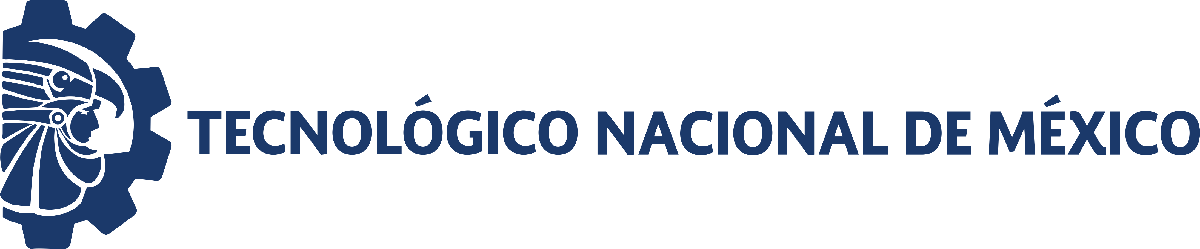                                 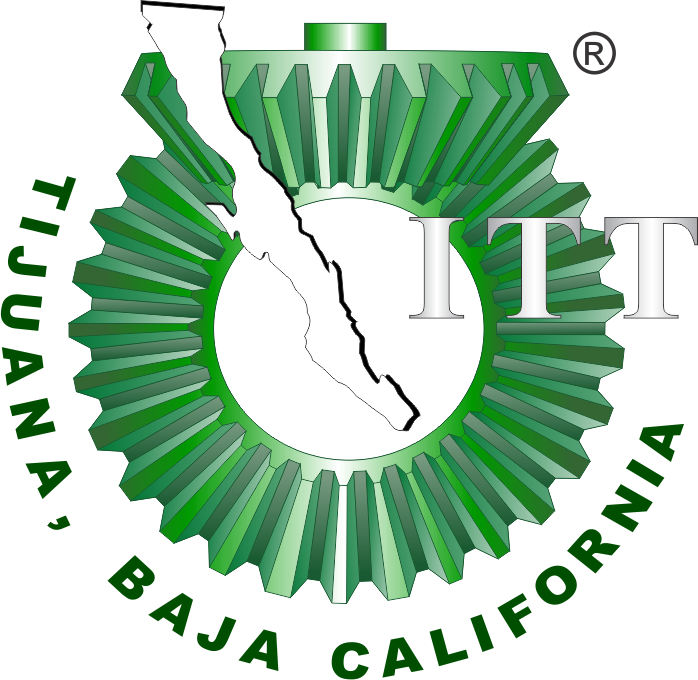

# Práctica 5: Analysis of biological systems.

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

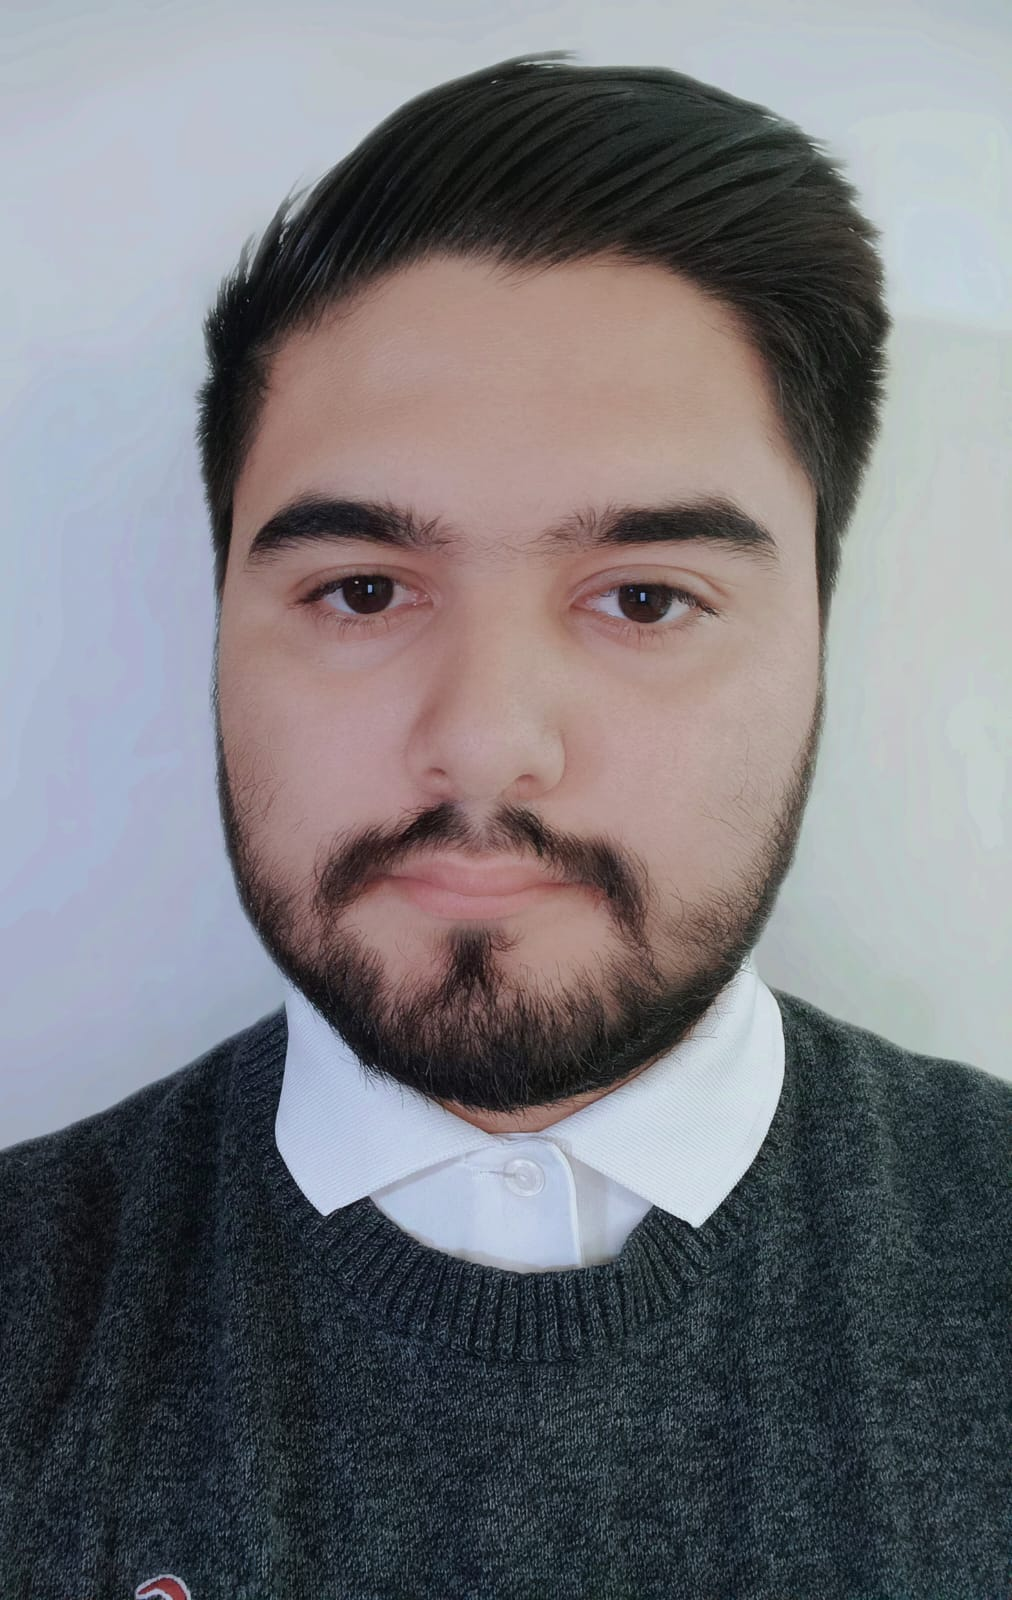

Nombre del alumno: **Jose Sebastian Delgado Soto**

Número de control: **C20212281**

Correo institucional: **l20212281@tectijuana.edu.mx**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## **Objetive**

Objective: Construct and analyze a mechanistic model of the dynamics between two biological variables.

## Chaotic Attractor(atractor caotico)

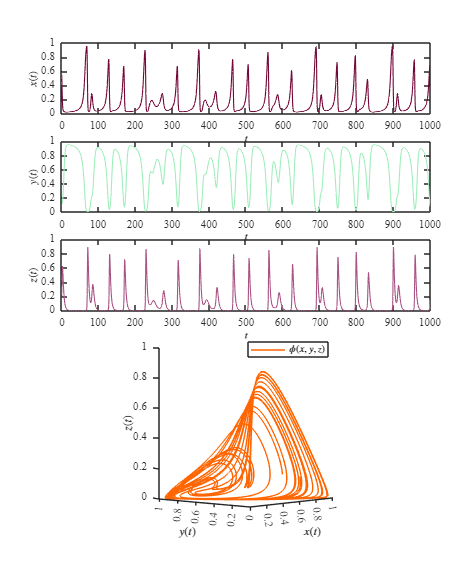

 clc; clear; close all; warning('off','all')
 r1 = 1; b1 = 1; a13 = 2.5; 
r2 = 0.6; b2 = 1; a21 = 1.5;
r3 = 3; a31 = 0.3; d3 = 0.4;
x0= 0.555;
y0 = 0.148;
z0 = 0.172;
a12 = 1;
tend= 1000;
P= [r1,b1,a13,r2,b2,a21,r3,a31,d3];
dt = 1E-2;
rhoi = 0;

 [t,x,y,z] = system(x0,y0,z0,P,a12,rhoi,dt,tend);
plotEDOs(t,x,y,z)
 exportgraphics(gcf,'Atractor Caótico.pdf','ContentType','vector')

## Periodic Orbit(orbita periodica)

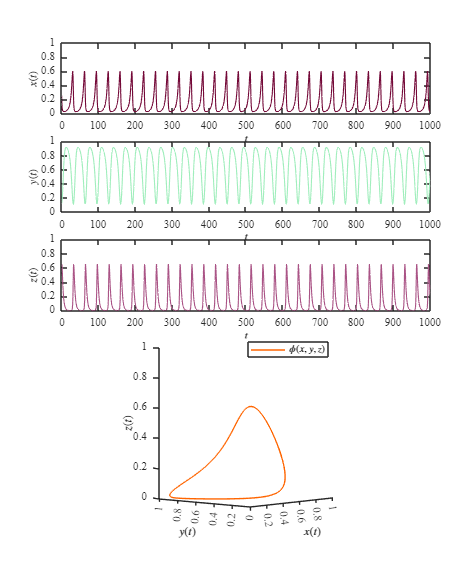

r1 = 1; b1 = 1; a13 = 2.5; 
r2 = 0.6; b2 = 1; a21 = 1.5;
r3 = 3; a31 = 0.3; d3 = 0.4;
x0= 0.254781;
y0 = 0.115167;
z0 = 0.600527;
a12 = 0.9;
tend= 1000;
P= [r1,b1,a13,r2,b2,a21,r3,a31,d3];
dt = 1E-2;
rhoi = 0;

 [t,x,y,z] = system(x0,y0,z0,P,a12,rhoi,dt,tend);
plotEDOs(t,x,y,z)
 exportgraphics(gcf,'Orbita periodica.pdf','ContentType','vector')

## Internal Limit Cycle(ciclo limite interno)

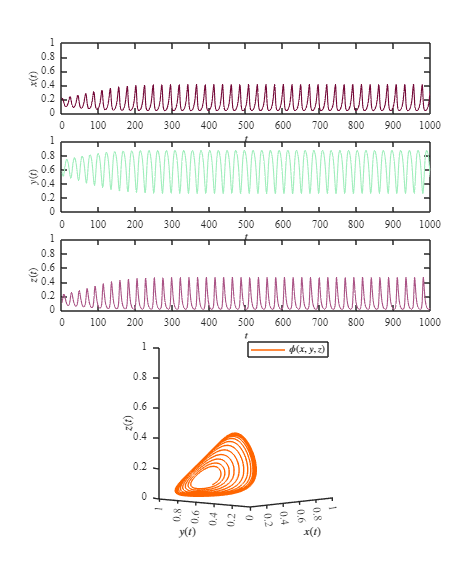

r1 = 1; b1 = 1; a13 = 2.5; 
r2 = 0.6; b2 = 1; a21 = 1.5;
r3 = 3; a31 = 0.3; d3 = 0.4;

x0= 0.2;
y0 = 0.6;
z0 = 0.1;
a12 = 0.8;
tend= 1000;
P= [r1,b1,a13,r2,b2,a21,r3,a31,d3];
dt = 1E-2;
rhoi = 0;

 [t,x,y,z] = system(x0,y0,z0,P,a12,rhoi,dt,tend);
plotEDOs(t,x,y,z)
 exportgraphics(gcf,'Ciclo limite interno.pdf','ContentType','vector')

## External Limit Cycle(ciclo limite externo)

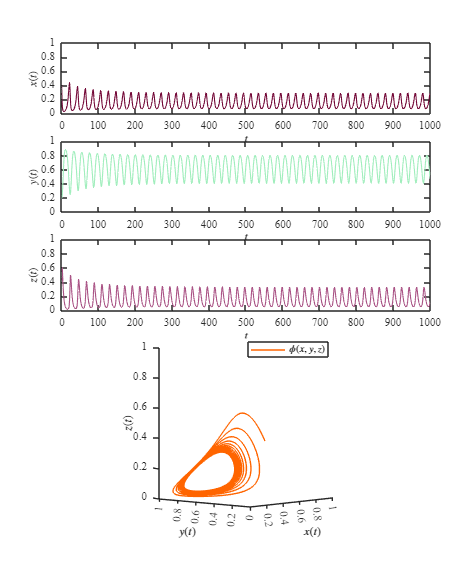

r1 = 1; b1 = 1; a13 = 2.5; 
r2 = 0.6; b2 = 1; a21 = 1.5;
r3 = 3; a31 = 0.3; d3 = 0.4;


x0= 0.4;
y0 = 0.2;
z0 = 0.4;
a12 = 0.75;
tend= 1000;
P= [r1,b1,a13,r2,b2,a21,r3,a31,d3];
dt = 1E-2;
rhoi = 0;

 [t,x,y,z] = system(x0,y0,z0,P,a12,rhoi,dt,tend);
plotEDOs(t,x,y,z)
 exportgraphics(gcf,'Ciclo limite externo.pdf','ContentType','vector')

## Convergence towards an equilibrium point(convergencia hacia un punto de equilibrio)

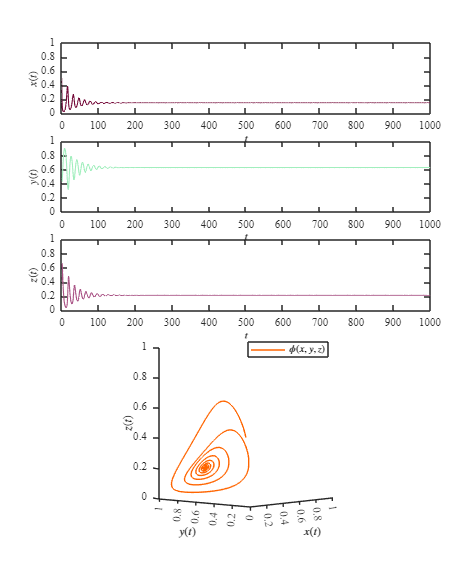


 r1 = 1; b1 = 1; a13 = 2.5; 
r2 = 0.6; b2 = 1; a21 = 1.5;
r3 = 3; a31 = 0.3; d3 = 0.4;


x0= 0.5;
y0 = 0.5;
z0 = 0.4;
a12 = 0.5;
tend= 1000;
P= [r1,b1,a13,r2,b2,a21,r3,a31,d3];
dt = 1E-2;
rhoi = 0;

 [t,x,y,z] = system(x0,y0,z0,P,a12,rhoi,dt,tend);
plotEDOs(t,x,y,z)
 exportgraphics(gcf,'convergencia hacia un punto de equilibrio.pdf','ContentType','vector')

## Convergence towards an equilibrium point(no normalizado)

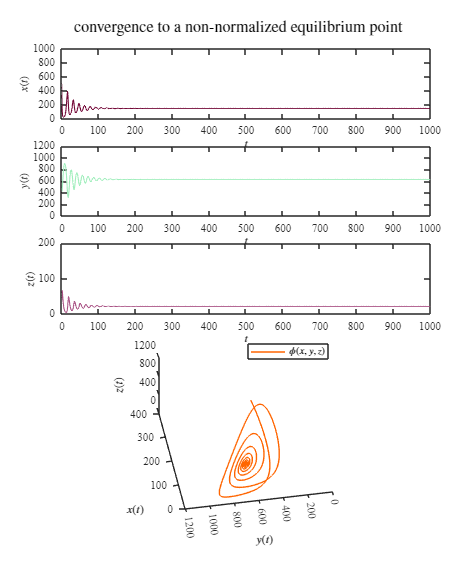

xmax =1E3;  ymax = 1E3; zmax= 1E2;
 
 r1 =1; b1 = 1/xmax; a13 = 2.5/zmax; 
r2 = 0.6; b2 = 1/ymax; a21 = 1.5/xmax;
r3 = 3/xmax; a31 = 0.3/xmax; d3 = 0.4;


x0= 0.5*xmax;
y0 = 0.5*ymax;
z0 = 0.4*zmax;
a12 = 0.5/ymax;
tend= 1000;
P= [r1,b1,a13,r2,b2,a21,r3,a31,d3];
dt = 1E-2;
rhoi = 0;

 [t,x,y,z] = system(x0,y0,z0,P,a12,rhoi,dt,tend);
plotEDOs2(t,x,y,z)
ttl = 'convergence to a non-normalized equilibrium point'; sgtitle(ttl,'Interpreter','Latex')
 exportgraphics(gcf,'convergencia hacia un punto de equilibrio.pdf','ContentType','vector')

## Equilibrium points and jacobian matrix

clc; clear; close all; warning('off','all')

% Definir variables simbólicas
syms x y z r1 b1 a13 r2 b2 a21 r3 a31 d3 a12 rhoi

% Ecuaciones del sistema
dx = r1*x*(1 - b1*x) - a12*x*y - a13*x*z;
dy = r2*y*(1 - b2*y) - a21*x*y;
dz = (r3 - a31)*x*z - d3*z + rhoi;

% Matriz Jacobiana del sistema
J = jacobian([dx, dy, dz], [x, y, z]);
fprintf('Jacobian matrix of the Lotka-Volterra system:\n'); disp(J)

Jacobian matrix of the Lotka-Volterra system:


$$\left(\begin{array}{ccc} -a_{12}\,y-a_{13}\,z-r_{1}\,\left(b_{1}\,x-1\right)-b_{1}\,r_{1}\,x & -a_{12}\,x & -a_{13}\,x\\ -a_{21}\,y & -a_{21}\,x-r_{2}\,\left(b_{2}\,y-1\right)-b_{2}\,r_{2}\,y & 0\\ -z\,\left(a_{31}-r_{3}\right) & 0 & -d_{3}-x\,\left(a_{31}-r_{3}\right) \end{array}\right)$$


dx = r1*x*(1 - b1*x) - a12*x*y - a13*x*z ==0;
dy = r2*y*(1 - b2*y) - a21*x*y ==0;
dz = (r3 - a31)*x*z - d3*z + rhoi ==0;
equilibria = solve([dx, dy, dz], [x, y, z]);

for i = 1:6
    xe(i,1) = simplify(equilibria.x(i));
    ye(i,1) = simplify(equilibria.y(i));
    ze(i,1) = simplify(equilibria.z(i));

   disp(['Equilibrium points of the system: ', num2str(i)])
    disp(['x', num2str(i), ' = ', char(xe(i,1))]);
    disp(['y', num2str(i), ' = ', char(ye(i,1))]);
    disp(['z', num2str(i), ' = ', char(ze(i,1))]);

end

Equilibrium points of the system: 1


x1 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) - b1*d3*r1)/(2*b1*r1*(a31 - r3))


y1 = 0


z1 = (a31*r1 - r1*r3 - (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3))


Equilibrium points of the system: 2


x2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3))


y2 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) + (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3))


z2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3))


Equilibrium points of the system: 3


x3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3))


y3 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) - (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3))


z3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3))


Equilibrium points of the system: 4


x4 = 0


y4 = 1/b2


z4 = rhoi/d3


Equilibrium points of the system: 5


x5 = -(r1*r3 - a31*r1 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*b1*r1*(a31 - r3))


y5 = 0


z5 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3))


Equilibrium points of the system: 6


x6 = 0


y6 = 0


z6 = rhoi/d3


## Equilibrium points

clear
a12i = [1;0.9;0.8;0.75;0.5];
r1 = 1; b1 = 1; a12 = 1; a13 = 2.5;
r2 = 0.6; b2 = 1; a21 = 1.5;
r3 = 3; a31 = 0.3; d3 = 0.4;
rhoi = 0;
for i = 1:numel(a12i)
    a12 = a12i(i);
    x1 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) - b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y1 = 0;
    z1 = (a31*r1 - r1*r3 - (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y2 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) + (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y3 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) - (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x4 = 0;
    y4 = 1/b2;
    z4 = rhoi/d3;

    x5 = -(r1*r3 - a31*r1 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y5 = 0;
    z5 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x6 = 0;
    y6 = 0;
    z6 = rhoi/d3;

    xe = [x1; x2; x3; x4; x5; x6]; ye = [y1; y2; y3; y4; y5; y6]; ze = [z1; z2; z3; z4; z5; z6];

    Eqs = array2table([xe, ye, ze], 'VariableNames', {'x*','y*','z*'});
    fprintf(['Equilibrium points with a12 = ',num2str(a12), '\n'])
    fprintf(['Treatment rhoi = ', num2str(rhoi), '\n'])
    disp(Eqs)
end

Equilibrium points with a12 = 1


Treatment rhoi = 0


        x*           y*           z*     
    ___________    _______    ___________

        0.14815          0        0.34074
        0.14815    0.62963       0.088889
    -4.5688e-17          1    -5.4826e-17
              0          1              0
              1          0     2.4672e-17
              0          0              0



Equilibrium points with a12 = 0.9


Treatment rhoi = 0


      x*         y*           z*     
    _______    _______    ___________

    0.14815          0        0.34074
    0.14815    0.62963        0.11407
      -0.08        1.2    -5.4826e-17
          0          1              0
          1          0     2.4672e-17
          0          0              0



Equilibrium points with a12 = 0.8


Treatment rhoi = 0


      x*         y*           z*     
    _______    _______    ___________

    0.14815          0        0.34074
    0.14815    0.62963        0.13926
       -0.2        1.5    -1.3706e-16
          0          1              0
          1          0     2.4672e-17
          0          0              0



Equilibrium points with a12 = 0.75


Treatment rhoi = 0


       x*         y*           z*    
    ________    _______    __________

     0.14815          0       0.34074
     0.14815    0.62963       0.15185
    -0.28571     1.7143    1.3706e-16
           0          1             0
           1          0    2.4672e-17
           0          0             0



Equilibrium points with a12 = 0.5


Treatment rhoi = 0


      x*         y*           z*    
    _______    _______    __________

    0.14815          0       0.34074
    0.14815    0.62963       0.21481
         -2          6             0
          0          1             0
          1          0    2.4672e-17
          0          0             0



## Equilibrium point Convergence towards an equilibrium point

clc; clear; close all; warning('off','all')
a12i = 0.5;
r1 = 1; b1 = 1; a12 = 0.5; a13 = 2.5;
r2 = 0.6; b2 = 1; a21 = 1.5;
r3 = 3; a31 = 0.3; d3 = 0.4;
rhoi = 1.1*(d3*r1)/a13;
for i = 1:numel(a12i)
    a12 = a12i(i);
    x1 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) - b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y1 = 0;
    z1 = (a31*r1 - r1*r3 - (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y2 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) + (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y3 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) - (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x4 = 0;
    y4 = 1/b2;
    z4 = rhoi/d3;

    x5 = -(r1*r3 - a31*r1 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y5 = 0;
    z5 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x6 = 0;
    y6 = 0;
    z6 = rhoi/d3;

    xe = [x1; x2; x3; x4; x5; x6]; ye = [y1; y2; y3; y4; y5; y6]; ze = [z1; z2; z3; z4; z5; z6];

    Eqs = array2table([xe, ye, ze], 'VariableNames', {'x*','y*','z*'});
    fprintf(['Equilibrium points with a12 = ',num2str(a12), '\n'])
    fprintf(['Treatment rhoi = ', num2str(rhoi), '\n'])
    disp(Eqs)
end

Equilibrium points with a12 = 0.5


Treatment rhoi = 0.176


       x*          y*         z*    
    _________    ______    _________

    -0.012761         0       0.4051
     -0.21756    1.5439      0.17824
      -1.6343    5.0857     0.036571
            0         1         0.44
       1.1609         0    -0.064364
            0         0         0.44



## Equilibrium point Convergence towards an equilibrium point (no normalizado)

clc; clear; close all; warning('off','all')
a12i = 0.5;
xmax =1E3;  ymax = 1E3; zmax= 1E2;
 r1 =1; b1 = 1/xmax; a12 = 0.5/ymax; a13 = 2.5/zmax; 
r2 = 0.6; b2 = 1/ymax; a21 = 1.5/xmax;
r3 = 3/xmax; a31 = 0.3/xmax; d3 = 0.4;



rhoi = 1.1*(d3*r1)/a13;
for i = 1:numel(a12i)
    a12 = a12i(i);
    x1 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) - b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y1 = 0;
    z1 = (a31*r1 - r1*r3 - (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y2 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) + (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y3 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) - (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x4 = 0;
    y4 = 1/b2;
    z4 = rhoi/d3;

    x5 = -(r1*r3 - a31*r1 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y5 = 0;
    z5 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x6 = 0;
    y6 = 0;
    z6 = rhoi/d3;

    xe = [x1; x2; x3; x4; x5; x6]; ye = [y1; y2; y3; y4; y5; y6]; ze = [z1; z2; z3; z4; z5; z6];

    Eqs = array2table([xe, ye, ze], 'VariableNames', {'x*','y*','z*'});
    fprintf(['Equilibrium points with a12 = ',num2str(a12), '\n'])
    fprintf(['Treatment rhoi = ', num2str(rhoi), '\n'])
    disp(Eqs)
end

Equilibrium points with a12 = 0.5


Treatment rhoi = 17.6


      x*         y*        z*   
    _______    ______    _______

    -12.761         0      40.51
        399    2.5013    -25.986
     148.67    628.33     -12533
          0      1000         44
     1160.9         0    -6.4364
          0         0         44



## Convergence towards an equilibrium point

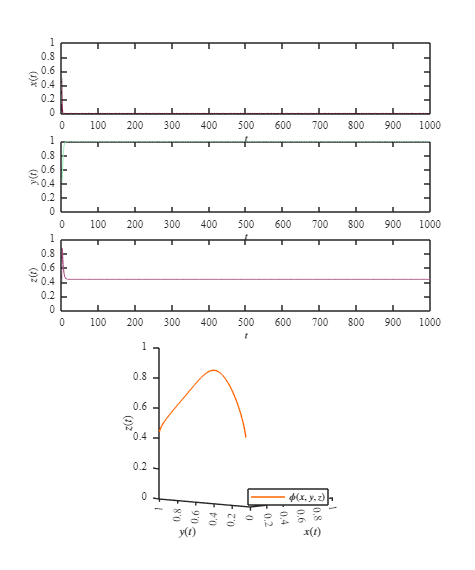


 r1 = 1; b1 = 1; a13 = 2.5; 
r2 = 0.6; b2 = 1; a21 = 1.5;
r3 = 3; a31 = 0.3; d3 = 0.4;


x0= 0.5;
y0 = 0.5;
z0 = 0.4;
a12 = 0.5;
tend= 1000;
P= [r1,b1,a13,r2,b2,a21,r3,a31,d3];
dt = 1E-2;
rhoi = 1.1*(d3*r1)/a13;

 [t,x,y,z] = system(x0,y0,z0,P,a12,rhoi,dt,tend);
plotEDOs(t,x,y,z)
 exportgraphics(gcf,'convergencia hacia un punto de equilibrio2.pdf','ContentType','vector')

## Convergence towards an equilibrium point(no normalizado)

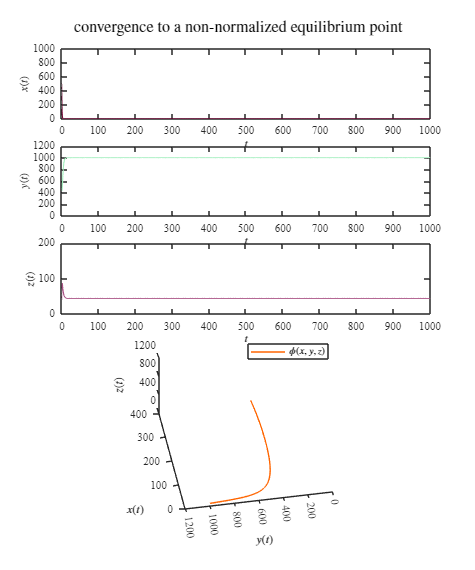

xmax =1E3;  ymax = 1E3; zmax= 1E2;
 
r1 =1; b1 = 1/xmax; a13 = 2.5/zmax; 
r2 = 0.6; b2 = 1/ymax; a21 = 1.5/xmax;
r3 = 3/xmax; a31 = 0.3/xmax; d3 = 0.4;


x0= 0.5*xmax;
y0 = 0.5*ymax;
z0 = 0.4*zmax;
a12 = 0.5/ymax;
tend= 1000;
P= [r1,b1,a13,r2,b2,a21,r3,a31,d3];
dt = 1E-2;
rhoi = 1.1*(d3*r1)/a13;

 [t,x,y,z] = system(x0,y0,z0,P,a12,rhoi,dt,tend);
plotEDOs2(t,x,y,z)
ttl = 'convergence to a non-normalized equilibrium point'; sgtitle(ttl,'Interpreter','Latex')
 exportgraphics(gcf,'convergencia hacia un punto de equilibrio3.pdf','ContentType','vector')

## Estabilidad local(sin tratamiento)

 clc; clear; close all; warning('off','all')
a12i = 0.5;
r1 = 1; b1 = 1; a12 = 1; a13 = 2.5;
r2 = 0.6; b2 = 1; a21 = 1.5;
r3 = 3; a31 = 0.3; d3 = 0.4;
rhoi = 0;
for i = 1:numel(a12i)
    a12 = a12i(i);
    x1 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) - b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y1 = 0;
    z1 = (a31*r1 - r1*r3 - (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y2 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) + (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y3 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) - (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x4 = 0;
    y4 = 1/b2;
    z4 = rhoi/d3;

    x5 = -(r1*r3 - a31*r1 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y5 = 0;
    z5 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x6 = 0;
    y6 = 0;
    z6 = rhoi/d3;

    x = [x1; x2; x3; x4; x5; x6]; y = [y1; y2; y3; y4; y5; y6]; z = [z1; z2; z3; z4; z5; z6];
fprintf(['Equilibrium points with a12 = ', num2str(a12), '\n'])
fprintf(['Treatment rhoi = ', num2str(rhoi), '\n'])

for j = 1:numel(x)
    J = [
        -a12*y(j) - a13*z(j) - r1*(b1*x(j) - 1) - b1*r1*x(j),   -a12*x(j),             -a13*x(j);
        -a21*y(j),                                             -a21*x(j) - r2*(b2*y(j) - 1) - b2*r2*y(j),   0;
        -z(j)*(a31 - r3),                                      0,                     -d3*x(j)*(a31 - r3)
    ];
    L(j,:) = eig(J);
end

Lambda1 = L(:,1);
Lambda2 = L(:,2);
Lambda3 = L(:,3);

Results = table(x, y, z, Lambda1, Lambda2, Lambda3);
disp(Results)
end

Equilibrium points with a12 = 0.5


Treatment rhoi = 0


       x          y           z              Lambda1               Lambda2              Lambda3     
    _______    _______    __________    __________________    __________________    ________________

    0.14815          0       0.34074    0.0059259+0.56303i    0.0059259-0.56303i    0.37778+0i      
    0.14815    0.62963       0.21481     -0.48241+0i            0.05824+0.41167i    0.05824-0.41167i
         -2          6             0         -0.8+1.077i           -0.8-1.077i        -2.16+0i      
          0          1             0         -0.6+0i                0.5+0i                0+0i      
          1          0    2.4672e-17           -1+0i               1.08+0i             -0.9+0i      
          0          0             0            0+0i                0.6+0i              

## Estabilidad local(con tratamiento)

 clc; clear; close all; warning('off','all')
a12i = 0.5;
xmax =1E3;  ymax = 1E3; zmax= 1E2;
 
r1 =1; b1 = 1/xmax; a13 = 2.5/zmax; 
r2 = 0.6; b2 = 1/ymax; a21 = 1.5/xmax;
r3 = 3/xmax; a31 = 0.3/xmax; d3 = 0.4;

a12 = 0.5/ymax;

rhoi = 1.1*(d3*r1)/a13;
for i = 1:numel(a12i)
    a12 = a12i(i);
    x1 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) - b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y1 = 0;
    z1 = (a31*r1 - r1*r3 - (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y2 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) + (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z2 = -((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) + a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 - b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 + a12*a31*r2 - a12*r2*r3 - a31*b2*r1*r2 + b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    y3 = (r1*(a21 - b1*r2))/(a12*a21 - b1*b2*r1*r2) - (a21*((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2))/(2*b2*r2*(a12*a21 - b1*b2*r1*r2)*(a31 - r3));
    z3 = ((a12^2*a21^2*d3^2 + a12^2*a31^2*r2^2 + a12^2*r2^2*r3^2 + a31^2*b2^2*r1^2*r2^2 + b2^2*r1^2*r2^2*r3^2 - 2*a12^2*a31*r2^2*r3 - 2*a12*a31^2*b2*r1*r2^2 - 2*a12*b2*r1*r2^2*r3^2 + b1^2*b2^2*d3^2*r1^2*r2^2 - 2*a31*b2^2*r1^2*r2^2*r3 + 2*a12^2*a21*a31*d3*r2 - 2*a12^2*a21*d3*r2*r3 + 4*a12*a31*b2*r1*r2^2*r3 + 2*a31*b1*b2^2*d3*r1^2*r2^2 - 2*b1*b2^2*d3*r1^2*r2^2*r3 + 4*a13*b1*b2^2*r1*r2^2*r3*rhoi + 4*a12*a13*a21*a31*b2*r2*rhoi - 2*a12*a21*a31*b2*d3*r1*r2 - 4*a12*a13*a21*b2*r2*r3*rhoi + 2*a12*a21*b2*d3*r1*r2*r3 - 2*a12*a21*b1*b2*d3^2*r1*r2 - 2*a12*a31*b1*b2*d3*r1*r2^2 + 2*a12*b1*b2*d3*r1*r2^2*r3 - 4*a13*a31*b1*b2^2*r1*r2^2*rhoi)^(1/2) - a12*a21*d3 - a12*a31*r2 + a12*r2*r3 + a31*b2*r1*r2 - b2*r1*r2*r3 + b1*b2*d3*r1*r2)/(2*a13*b2*r2*(a31 - r3));

    x4 = 0;
    y4 = 1/b2;
    z4 = rhoi/d3;

    x5 = -(r1*r3 - a31*r1 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*b1*r1*(a31 - r3));
    y5 = 0;
    z5 = (a31*r1 - r1*r3 + (r1*(a31^2*r1 + r1*r3^2 + b1^2*d3^2*r1 - 2*a31*r1*r3 + 4*a13*b1*r3*rhoi - 2*b1*d3*r1*r3 - 4*a13*a31*b1*rhoi + 2*a31*b1*d3*r1))^(1/2) + b1*d3*r1)/(2*a13*(a31 - r3));

    x6 = 0;
    y6 = 0;
    z6 = rhoi/d3;

    x = [x1; x2; x3; x4; x5; x6]; y = [y1; y2; y3; y4; y5; y6]; z = [z1; z2; z3; z4; z5; z6];
fprintf(['Equilibrium points with a12 = ', num2str(a12), '\n'])
fprintf(['Treatment rhoi = ', num2str(rhoi), '\n'])

for j = 1:numel(x)
    J = [
        -a12*y(j) - a13*z(j) - r1*(b1*x(j) - 1) - b1*r1*x(j),   -a12*x(j),             -a13*x(j);
        -a21*y(j),                                             -a21*x(j) - r2*(b2*y(j) - 1) - b2*r2*y(j),   0;
        -z(j)*(a31 - r3),                                      0,                     -d3*x(j)*(a31 - r3)
    ];
    L(j,:) = eig(J);
end

Lambda1 = L(:,1);
Lambda2 = L(:,2);
Lambda3 = L(:,3);

Results = table(x, y, z, Lambda1, Lambda2, Lambda3);
disp(Results)
end

Equilibrium points with a12 = 0.5


Treatment rhoi = 17.6


       x         y          z       Lambda1    Lambda2     Lambda3 
    _______    ______    _______    _______    ________    ________

    -12.761         0      40.51    0.18676    -0.18778     0.61914
        399    2.5013    -25.986    -1.3482       1.176     0.20262
     148.67    628.33     -12533     13.906     -14.086    -0.18466
          0      1000         44          0        -0.6      -500.1
     1160.9         0    -6.4364    -1.3543      1.4472     -1.1414
          0         0         44          0        -0.1         0.6



## Functions:

## sistema

function [t,x,y,z] = system(x0,y0,z0,P,a12,rhoi,dt,tend)

r1 = P(1); b1 = P(2); a13 = P(3);
r2 = P(4); b2 = P(5); a21 = P(6);
r3 = P(7); a31 = P(8); d3 = P(9);

t = (0:dt:tend)';
n = round(tend/dt);
x = zeros(n+1,1); x(1) = x0;
y = zeros(n+1,1); y(1) = y0;
z = zeros(n+1,1); z(1) = z0;
 

  for i = 1:n
            [fx,fy,fz] = f(x(i),y(i),z(i));
            xn = x(i) + fx*dt;
            yn = y(i) + fy*dt;
            zn = z(i) + fz*dt;
            [fxn,fyn,fzn] = f(xn, yn,zn);
            x(i+1) = x(i) + (fx + fxn)*dt/2;
            y(i+1) = y(i) + (fy + fyn)*dt/2;
            z(i+1) = z(i) + (fz + fzn)*dt/2;
   end

        function [dx, dy,dz] = f(x,y,z)
            dx = r1*x*(1-b1*x)-a12*x*y-a13*x*z;
            dy = r2*y*(1-b2*y)-a21*x*y;
            dz = (r3- a31)*x*z-d3*z + rhoi;
        end

end


## Solutions and systems.

 function plotEDOs(t,x,y,z)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[1,1,15,18])
     colores = [116, 9, 56;
           161, 238, 189;
           170, 84, 134;
           255, 101, 0;
           123, 211, 234;
           181, 159, 120;
            42,  54,  99;
            26,  26,  29;
            254, 236, 55;
            165, 182, 141;

                 ]/255;
   
    subplot(5, 4, 1:4);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,x,'-','LineWidth',1,'Color', colores(1,:))
    xlabel('$t$','Interpreter','Latex')
    ylabel('$x(t)$','Interpreter','Latex')
    xlim([0 1000]); xticks(0:100:1000)
    ylim([0 1]); yticks(0:0.2:1)
    
    subplot(5, 4, 5:8);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,y,'-','LineWidth',1, 'Color', colores(2,:))
    xlabel('$t$','Interpreter','Latex')
 
    ylabel('$y(t)$','Interpreter','Latex')
    xlim([0 1000]); xticks(0:100:1000)
    ylim([0 1]); yticks(0:0.2:1)
    subplot(5, 4, 9:12);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,z,'-','LineWidth',1,'Color', colores(3,:))
    xlabel('$t$','Interpreter','Latex')
    ylabel('$z(t)$','Interpreter','Latex')
    xlim([0 1000]); xticks(0:100:1000)
    ylim([0 1]); yticks(0:0.2:1)
    subplot(5, 4, [14, 15, 18, 19]);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box off; grid off;
    plot3(x, y, z, '-', 'LineWidth', 0.5,'Color', colores(4,:))
    set(gca, 'XDir', 'reverse');
    set(gca, 'YDir', 'reverse');
    xlabel('$x(t)$', 'Interpreter', 'Latex');
    ylabel('$y(t)$', 'Interpreter', 'Latex');
    zlabel('$z(t)$', 'Interpreter', 'Latex');
    view(132, 5);
    xlim([0 1]); ylim([0 1]); zlim([0 1]);
    xticks(0.2:0.2:1); yticks(0:0.2:1); zticks(0:0.2:1);
    L = legend('$\phi(x,y,z)$');
    set(L,'Interpreter','Latex','Location','Best','Box','On')
 end




 function plotEDOs2(t,x,y,z)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[1,1,15,18])
     colores = [116, 9, 56;
           161, 238, 189;
           170, 84, 134;
           255, 101, 0;
           123, 211, 234;
           181, 159, 120;
            42,  54,  99;
            26,  26,  29;
            254, 236, 55;
            165, 182, 141;

                 ]/255;
   
    subplot(5, 4, 1:4);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,x,'-','LineWidth',1,'Color', colores(1,:))
    xlabel('$t$','Interpreter','Latex')
    ylabel('$x(t)$','Interpreter','Latex')
    xlim([0 1000]); xticks(0:100:1000)
    ylim([0 1000]); yticks(0:200:1000)
    
    subplot(5, 4, 5:8);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,y,'-','LineWidth',1, 'Color', colores(2,:))
    xlabel('$t$','Interpreter','Latex')
 
    ylabel('$y(t)$','Interpreter','Latex')
    xlim([0 1000]); xticks(0:100:1000)
   ylim([0 1200]); yticks(0:200:1200)
    subplot(5, 4, 9:12);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box on; grid off;
    plot(t,z,'-','LineWidth',1,'Color', colores(3,:))
    xlabel('$t$','Interpreter','Latex')
    ylabel('$z(t)$','Interpreter','Latex')
    xlim([0 1000]); xticks(0:100:1000)
    ylim([0 200]); yticks(0:100:200)
    subplot(5, 4, [14, 15, 18, 19]);
    set(gca,'FontName','Times New Roman'); fontsize(10,'points');
    hold on; box off; grid off;
    plot3(x, y, z, '-', 'LineWidth', 0.5,'Color', colores(4,:))
    set(gca, 'XDir', 'reverse');
    set(gca, 'YDir', 'reverse');
    xlabel('$x(t)$', 'Interpreter', 'Latex');
    ylabel('$y(t)$', 'Interpreter', 'Latex');
    zlabel('$z(t)$', 'Interpreter', 'Latex');
    xlim([0 400]); ylim([0 1200]); zlim([0 1200]);
    xticks(0:100:400); yticks(0:200:1200); zticks(0:400:1200);
    view(80, 60); 

    L = legend('$\phi(x,y,z)$');
    set(L,'Interpreter','Latex','Location','Best','Box','On')
 end